# **Lab 1 - GPH 333 - Topography**

Nate Crummett

## Opening Data

Earth = readtable("C:\Users\rncru\Downloads\GPH333\ave_ETOPO1_0.1_10k.xlsx");

Venus = readtable("C:\Users\rncru\Downloads\GPH333\ave_Venus719_10k.xlsx");

*Make sure the data address is right, or nothing works.*

## Question One

r = 6371;
AreaEarth = 4*pi*r^2;
lenE = length(Earth.lon);
AreaCoverage = 10000*lenE;

assert(1000000 > abs(AreaEarth - AreaCoverage))

The assertion holds, so the data coveres the entire 'sphere' to reasonable accuracy.

## Question Two

#### A)

meanEarth = mean(Earth.elevation_m_);
meanEarth = round(meanEarth, 2, "decimals");
disp("Mean Earth elevation is " + meanEarth + " m")

Mean Earth elevation is -2440.87 m


#### B) 

Earth's average elevation is below zero because the world has more area under water than above water. Or in other worlds more oceans than land.

#### C)

medianEarth = median(Earth.elevation_m_);
medianEarth = round(medianEarth, 2, "decimals");
disp("Median Earth elevation is " + medianEarth + " m")

Median Earth elevation is -3291.66 m


#### D)

The difference between mean and median implies that there is some type of outlier or skewness that is affecting mean but not median. Median is much more robust than mean to the presence of outliers in data. There is probably something positive that is dragging the mean further from the median.

## Question Three

#### A)

Earth's elevation histogram:

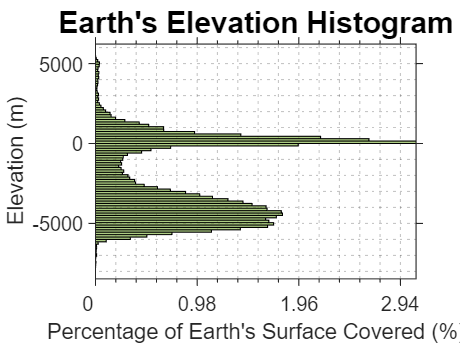

bins = 89;

histogram(Earth.elevation_m_,bins,"FaceColor", [0.4660 0.6740 0.1880]);
ax = gca;
ax.View = [90 -90];
yt = ax.YTick;
ytix = linspace(0,max(yt)/length(Earth.elevation_m_)*100,length(yt));
ax.YTickLabel = round(ytix, 2, "decimals");
ax.TickDir = "out";
ax.TitleFontSizeMultiplier = 1.5;
grid minor
ax.YMinorTick = "on";
ax.TickLength = [0.02 0.05];
title("Earth's Elevation Histogram")
xlabel("Elevation (m)")
ylabel("Percentage of Earth's Surface Covered (%)")

#### B)

The histogram has two peaks, unlike a normal distribution with one peak.

#### C)

The bin value of the top peak is [0 150]

The bin value of the bottom peak is [-4500 -4350]

The peaks represent the average value of two different distributions. The peaks are at different hights because they represent different crust types (ocean and continent). These crusts have different densities, so they sit at different hights on the mantle.

## Question Four

#### A)

meanVenus = mean(Venus.elevation_m_);
meanVenus = round(meanVenus, 2, "decimals");

meanVenus = 0.1900

disp("The mean elevation of Venus is " + meanVenus + " m")

The mean elevation of Venus is 0.19 m



medianVenus = median(Venus.elevation_m_);
medianVenus = round(medianVenus, 2, "decimals");
disp("The median elevation of Venus is " + medianVenus + " m")

The median elevation of Venus is -195.17 m


#### B)

assert(abs(medianEarth - meanEarth) > abs(medianVenus - meanVenus))

The assertion does not fail, so the difference is less. This tells us their is less deviance from norma distribution in Venus' elevation.

#### C)

Venus' elevation histogram:

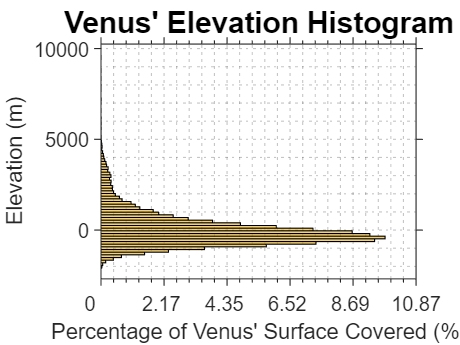

binsV = 80;

histogram(Venus.elevation_m_,binsV,"FaceColor",[0.9290 0.6940 0.1250])
av = gca;
av.View = [90 -90];
yv = av.YTick;
yvix = linspace(0, max(yv)/length(Venus.elevation_m_)*100, length(yv));
av.YTickLabel = round(yvix,2,"decimals");
av.TickLength = [0.02 0.05];
av.TitleFontSizeMultiplier = 1.5;
title("Venus' Elevation Histogram")
av.TickDir = "out";
grid minor
av.YMinorTick = "on";
xlabel("Elevation (m)")
ylabel("Percentage of Venus' Surface Covered (%)")

#### D)

Dominant elevation is [-483 -336]

This distribution has a single peak, unlike Earth. Therefore Venus resembles a normal disribution much better than Earth. Venus has a larger outier though, unlike Earth.

#### E)

The distribution of rock densities on Venus is much more uniform than that of Earth. There is probably one dominant type.

## Question 5

#### A)

[pa0,pb0,~,~] = minfunc(Earth.elevation_m_,0);
pa0 = round(pa0, 3, "significant");
pb0 = round(pb0, 3, "significant");
disp("Percentage of Earth above sea level: " + pa0 + "%")

Percentage of Earth above sea level: 28%


disp("Percentage of Earth below sea level: " + pb0 + "%")

Percentage of Earth below sea level: 72%


#### B)

[pa130,~,~,~] = minfunc(Earth.elevation_m_,-130);
q5b = (pa130 - pa0)/pa0 * 100;
q5b = round(q5b, 3, "significant");
disp(q5b + "% more land exposed when sea level was 130 m lower.")

12.9% more land exposed when sea level was 130 m lower.


#### C)

[pa500,~,~,~] = minfunc(Earth.elevation_m_,500);
q5c = pa0 - pa500;
q5c = round(q5c, 3, "significant");
disp(q5c + "% is the percentage of Earth's surface between 0 and 500 m.")

16.9% is the percentage of Earth's surface between 0 and 500 m.


#### D)

[pa4500,pb4500,~,~] = minfunc(Earth.elevation_m_,-4500);
[pa6000,pb6000,~,~] = minfunc(Earth.elevation_m_,-6000);
pcov4500 = (pb0 - pb4500)/pb0 * 100;
pcov6000 = (pb0 - pb6000)/pb0 * 100;
q5d = pcov6000 - pcov4500;
q5d = round(q5d, 3, "significant");
disp("Alvin is able to cover " + q5d + "% more of the ocean than before!")

Alvin is able to cover 34.8% more of the ocean than before!


## Question Six

#### A)

Earth's hypsometric curve:

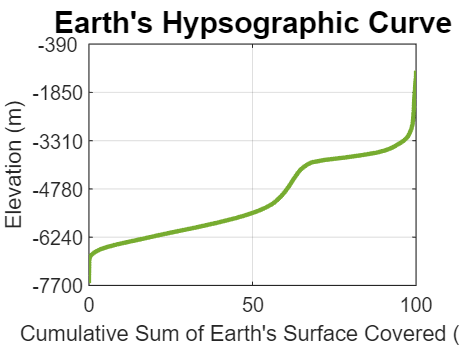

sEarth = sort(Earth.elevation_m_); %low to high
binData = discretize(Earth.elevation_m_,89);
tabData = tabulate(binData);
tabData(:,4) = cumsum(tabData(:,3));

plot(tabData(:,4),tabData(:,1),"Color",[0.4660 0.6740 0.1880],...
    "LineWidth",2)
axh = gca;
yth = axh.YTick;
yTickH = linspace(min(Earth.elevation_m_),max(Earth.elevation_m_),...
    length(yth));
axh.YTickLabel = round(yTickH, -1, "decimals");
grid on
title("Earth's Hypsographic Curve")
axh.TitleFontSizeMultiplier = 1.5;
xlabel("Cumulative Sum of Earth's Surface Covered (%)")
ylabel("Elevation (m)")

#### B)

Venus' hypsometric curve:

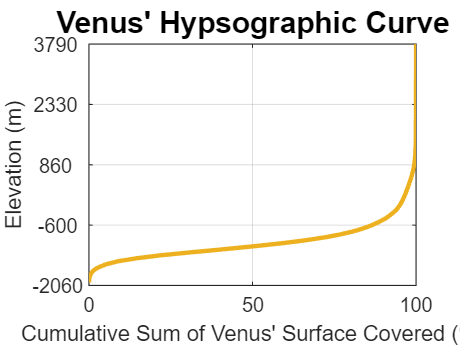

sVenus = sort(Venus.elevation_m_); %low to high
binDataV = discretize(Venus.elevation_m_,80);
tabDataV = tabulate(binDataV);
tabDataV(:,4) = cumsum(tabDataV(:,3));

plot(tabDataV(:,4),tabDataV(:,1),"Color",[0.9290 0.6940 0.1250],...
    "LineWidth",2)
avh = gca;
yvh = avh.YTick;
yTickV = linspace(min(Venus.elevation_m_),max(Venus.elevation_m_),...
    length(yvh));
avh.YTickLabel = round(yTickV, -1, "decimals");
grid on
title("Venus' Hypsographic Curve")
avh.TitleFontSizeMultiplier = 1.5;
xlabel("Cumulative Sum of Venus' Surface Covered (%)")
ylabel("Elevation (m)")

## Question Seven

If there were significant erosion, everything would eventually be 'flat'. Since erosion is always ongoing, why doesn't the Earth have a normal elevation distribution? Plate tectonics is the answer. They counter act the erosion.

## Functions

function [percAbove, percBelow, sData, idxmin] = minfunc(data, minvalue)
    sData = sort(data); %low to high
    [~, idxmin] = min(abs(sData - minvalue));
    len = length(sData);
    percBelow = length(sData(1:idxmin))/len * 100;
    percAbove = length(sData(idxmin + 1:end))/len * 100;
end